# SC42025 Filtering & Identification

**MATLAB EXERCISE HW3**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf').**

Consider the following Output Error system:


$$y(k) = \frac{b_1q^{-1}+b_2q^{-2}+b_3q^{-3}}{1+a_1q^{-1}+2_2q^{-2}+a_3q^{-3}+a_4q^{-4}+a_5q^{-5}}u(k) + e(k) .$$


close all; clear; clc; 
addpath('./function_folder')

load iodata.mat

## **Questions **

**a)  **Parameterize the system using the observable canonical form.

*Answer**: *

**b) **How many parameters do we have in part (a) ($\theta\in\mathbb{R}^p$)*?* Represent as $\theta=\pmatrix{
    \theta_A\cr \theta_B \cr \theta_{x_0}}$.

*Answer**: *

There are a total of 13 parameters.

**c)  **We are now going to implement a  Prediction Error method ($\texttt{pem.m}$) for the Output Error system. We will do this in the following four steps:

I. Derive expressions for $\frac{\partial \bar{A} \left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial \bar{B} \left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial K\left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial C\left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial D\left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial x_0 \left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$ $(\textrm{for all\,} p)$.

II. Based on the result in part (a), implement a MATLAB function that computes the state-space matrices from the parameter vector $\theta$. (*Look at* $\texttt{theta2matrices.m}$ *in the provided template*).

[~] = test_theta2matrices;

Nice job! theta2matrices is correct!


III. Write a function $\texttt{simsystem.m}$ that simulates a dynamic system given any input vector $u$ and matrices $A,B,C,D$, as well as initial condition $x(0)$.

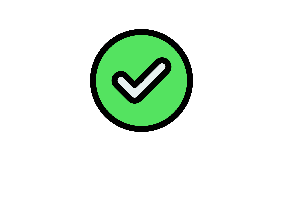

Nice job! simsystem is correct!


[~] = test_simsystem;

IV. 

- Implement a function $\texttt{jacobian.m}$ that calculates the Jacobian vector.

Nice job! jacobian is correct!


[~] = test_jacobian;

- Implement a function $\texttt{hessian.m}$ that calculates the approximated Hessian matrix.

Nice job! hessian is correct!


[~] = test_hessian;

**Note**: The convergence loop for the regularized Gauss-Newton algorithm is already implemented in the $\texttt{pem.m}$ function. There is no reason to edit this.

**d) **Choose two different initial guesses for $\theta$. For each guess, train two models such that the first model is obtained from the first 5000 samples and the second one is obtained from the first 10000 samples (from the given iodata.mat). Then, apply all four identified models on **the validation set** and plot the predicted output of all models (only for the validation set) in one figure. Add the numerical values of the VAF and the RMSE to the legend of this figures. (Do not forget to label the models properly!)

% split data

ut1 = u(1:5000);            % input for train-set 1
ut2 = u(1:10000);           % input for train-set 2
uv = u(10001:end);          % input for validation-set

yt1 = ymeas(1:5000);        % output for train-set 1
yt2 = ymeas(1:10000);       % output for train-set 2
yv = ymeas(10001:end);      % output for validation-set

lambda = 1000;
maxiter = 500;

%theta set 1
theta1 = [-1/20 -1/1000 -1/100000 -1/20000000 -1/10000000000 3/2 3/4 1/8 0*ones(1,5)]';
[A01,B01,C01,D01,x0i1] = theta2matrices(theta1);

%5k data
[A11,B11,C11,D11,x0f11,J11,H11] = pem(theta1,A01,B01,C01,D01,x0i1,yt1,ut1,lambda,maxiter);
[y5kt1,~] = simsystem(A11,B11,C11,D11,x0f11,uv);
rms5kt1 = rms(yv-y5kt1)

rms5kt1 = 0.7844

vaf5kt1 = max(0,(1 - rms(yv-y5kt1)/rms(yv))*100)

vaf5kt1 = 87.6474

%10k data
[A12,B12,C12,D12,x0f12,J12,H12] = pem(theta1,A01,B01,C01,D01,x0i1,yt2,ut2,lambda,maxiter);
[y10kt1,~] = simsystem(A12,B12,C12,D12,x0f12,uv);
rms10kt1 = rms(yv-y10kt1)

rms10kt1 = 0.7793

vaf10kt1 = max(0,(1 - rms(yv-y10kt1)/rms(yv))*100)

vaf10kt1 = 87.7270


%theta set 2
theta2 = [1/4 -1/200 1/20000 -1/4000000 1/2000000000 3/2 3/4 1/8 1*ones(1,5)]';
[A02,B02,C02,D02,x0i2] = theta2matrices(theta2);

%5k data
[A21,B21,C21,D21,x0f21,J21,H21] = pem(theta2,A02,B02,C02,D02,x0i2,yt1,ut1,lambda,maxiter);
[y5kt2,~] = simsystem(A21,B21,C21,D21,x0f21,uv);
rms5kt2 = rms(yv-y5kt2)

rms5kt2 = 0.6687

vaf5kt2 = max(0,(1 - rms(yv-y5kt2)/rms(yv))*100)

vaf5kt2 = 89.4688


%10k data
[A22,B22,C22,D22,x0f22,J22,H22] = pem(theta2,A02,B02,C02,D02,x0i2,yt2,ut2,lambda,maxiter);
[y10kt2,~] = simsystem(A22,B22,C22,D22,x0f22,uv);
rms10kt2 = rms(yv-y10kt2)

rms10kt2 = 0.6631

vaf10kt2 = max(0,(1 - rms(yv-y10kt2)/rms(yv))*100)

vaf10kt2 = 89.5571

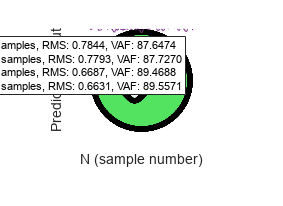



close all
plot(y5kt1)
hold on
plot(y10kt1)
plot(y5kt2)
plot(y10kt2)

xlabel('N (sample number)')
ylabel('Predicted output')
legend('Theta 1, 5k samples, RMS: 0.7844, VAF: 87.6474',...
    'Theta 1, 10k samples, RMS: 0.7793, VAF: 87.7270',...
    'Theta 2, 5k samples, RMS: 0.6687, VAF: 89.4688',...
    'Theta 2, 10k samples, RMS: 0.6631, VAF: 89.5571')

**e) **According to the result in (d), report the system parameters $a_1$, $a_2$, $a_3$, $a_4$, $a_5$, $b_1$, $b_2$, $b_3$ for the best identified model. Explain how you chose the best model.

*Answer**: *

## Functions

Implement your functions in the templates below. 

*You may implement additional functions for your convenience.*

function [Abar,Bbar,C,D,x0] = theta2matrices(theta)
% Function INPUT
% theta     Paramter vector (vector of size 'number of parameters' x 1)


% Function OUTPUT
% Abar      System matrix A (matrix of size n x n)
% Bbar      System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)

% YOUR CODE HERE

Abar = [[0; 0; 0; 0] eye(4); 0 0 0 0 0];
Bbar = zeros(5,1);
C = [1 0 0 0 0];
D = 0;
x0 = theta(9:13);

Abar(1:5,1) = theta(1:5);
Bbar(1:3) = theta(6:8); 


end

function [y, x] = simsystem(A, B, C, D, x0, u)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
n = size(A, 1); 
%  m = size(B, 2); 
l = size(C, 1);
N = size(u, 1); 
%
% Function INPUT
% A system matrix (matrix of size n x n)
% B system matrix (matrix of size n x m)
% C system matrix (matrix of size l x n)
% D system matrix (matrix of size l x m)
% x0 initial state (vector of size n x one)
% u system input (matrix of size N x m)
%
% Function OUTPUT
% x state of system (vector of size N x n)
% y system output (matrix of size N x l)

x = zeros(N,n);
x(1,:) = x0';
y = zeros(N,l);

% YOUR CODE HERE

for i = 1:N

    y(i,:) = C*(x(i,:)') + D * (u(i,:)');
    x(i+1,:) = A*(x(i,:)') + B * (u(i,:)');

end

x = (x(1:end-1,:)); %x1 to x3

end

function J = jacobian(psi,E)
% Instructions:
% This function calculates the Jacobian vector in the Gauss-Newton
% algorithm
%
%  p = size(theta); 
N = size(E, 1); 
%  l = size(C, 1);
%
% Function INPUT
% psi derivative of estimation error wrt theta (matrix of size l*N x p)
% E estimation error vector (vector of size l*N x one)
%
% Function OUTPUT
% J Jacobian vector (vector of size p x one)


% YOUR CODE HERE

J = (2/N) * psi' * E;

end

function H = hessian(psi)
% Instructions:
% This function calculates the approximated Hessian matrix in the Gauss-Newton
% algorithm
%
%  p = size(theta); 
N = size(psi, 1); 
%  l = size(C, 1);
%
% Function INPUT
% psi derivative of estimation error wrt theta (matrix of size l*N x p)
%
% Function OUTPUT
% H Hessian matrix (matrix of size p x p)


% YOUR CODE HERE

H = 2/N*((psi)'*(psi));


end

function [Abar,Bbar,C,D,x0, J, H] = pem(theta,A0,B0,C0,D0,x00,y,u,lambda,maxiter)
% Instructions:
% Implement your Prediction Error Method for the Output Error system here.
% Use the following function inputs and outputs.
%
% Function INPUT
% theta  Paramter vector (size: depends on your mapping choice)
% A0 Initial guess for system matrix A (matrix of size n x n)
% B0 Initial guess for system matrix B (matrix of size n x m)
% C0 Initial guess for system matrix C (matrix of size l x n)
% D0 Initial guess for system matrix D (matrix of size l x m)
% x00 Initial guess for initial state (vector of size n x one)
% u System input (matrix of size N x m)
% y System output (matrix of size N x l)
% lambda regularization parameter (scalar)
% maxiter Maximum number of iterations (scalar)
%
%
% Function OUTPUT
% Abar Estimate of system matrix A (matrix of size n x n)
% Bbar Estimate of system matrix B (matrix of size n x m)
% C Estimate of system matrix C (matrix of size l x n)
% D Estimate of system matrix D (matrix of size l x m)
% x0 Estimate of initial state (vector of size n x one)


% loop counters
p = length(theta);
N = length(u);

%initialization
A = A0;
B = B0;
C = C0;
D = D0;
x0 = x00;

% Gauss-Newton

% initialize
converged = false;
maxiter_reached = false;
iter = 1;

while ~converged && ~maxiter_reached

    %calculation of error vector
    [y_hat, x_hat] = simsystem(A,B,C,D,x0,u);
    E = y - y_hat;

    %psi calculation
    psi = zeros(N,p); %preallocation

    for j = 1:p

        [dadtp,dbdtp,dx0dtp] = pthderivative(j);
                
        [dydtp, ~] = simsystem(A,[dadtp dbdtp],C,zeros(1,6),dx0dtp,[x_hat u]);

        psi(:,j) = -1*dydtp;
        
    end

    J = jacobian(psi,E);
    H = hessian(psi);

    theta_new = theta - (H + lambda*eye(size(H,1))) \ J;
    [A,B,C,D,x0]=theta2matrices(theta_new);

    % Check convergence
    if norm(theta_new - theta) < 1e-3 
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end

    theta = theta_new; 
    iter = iter + 1;

end


% YOUR CODE HERE

Abar = A; 
Bbar = B;

end

function [dadtp, dbdtp, dx0dtp] = pthderivative(p)
    
    switch p

        case 1
            dadtp = zeros(5,5); dadtp(1,1) = 1;
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1);
        case 2
            dadtp = zeros(5,5); dadtp(2,1) = 1;
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1);
        case 3
            dadtp = zeros(5,5); dadtp(3,1) = 1;
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1);
        case 4
            dadtp = zeros(5,5); dadtp(4,1) = 1;
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1);
        case 5
            dadtp = zeros(5,5); dadtp(5,1) = 1;
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1);
        case 6
            dadtp = zeros(5,5);
            dbdtp = zeros(5,1); dbdtp(1,1) = 1;
            dx0dtp = zeros(5,1);
        case 7 
            dadtp = zeros(5,5);
            dbdtp = zeros(5,1); dbdtp(2,1) = 1;
            dx0dtp = zeros(5,1);
        case 8
            dadtp = zeros(5,5);
            dbdtp = zeros(5,1); dbdtp(3,1) = 1;
            dx0dtp = zeros(5,1);
        case 9 
            dadtp = zeros(5,5);
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1); dx0dtp(1,1) = 1;
        case 10
            dadtp = zeros(5,5);
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1); dx0dtp(2,1) = 1;
        case 11
            dadtp = zeros(5,5);
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1); dx0dtp(3,1) = 1;
        case 12
            dadtp = zeros(5,5);
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1); dx0dtp(4,1) = 1;
        case 13 
            dadtp = zeros(5,5);
            dbdtp = zeros(5,1);
            dx0dtp = zeros(5,1); dx0dtp(5,1) = 1;
        otherwise
            warning('unexpected behaviour')
    end
end
